s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gp=40/(s^2+3*s+4.5)

Gp =
 
        40
  ---------------
  s^2 + 3 s + 4.5
 
Continuous-time transfer function.




zpk(Gp)

ans =
 
         40
  ----------------
  (s^2 + 3s + 4.5)
 
Continuous-time zero/pole/gain model.




Gs=1

Gs = 1

Gr=1

Gr = 1

Ga=-0.09

Ga = -0.0900

Gf=1

Gf = 1

kc=3.8*-1

kc = -3.8000


wc=1.3

wc = 1.3000

Tp0=1.024

Tp0 = 1.0240

Sp0=1.33

Sp0 = 1.3300

Kd=1

Kd = 1



PI=1+s/(2.16666666666667)

PI =
 
  s + 2.167
  ---------
    2.167
 
Continuous-time transfer function.



Ri=(1+s/(2.5498*1.3*10^-2))/(1+s/(1.3*10^-2))

Ri =
 
   0.013 s + 0.0004309
  ---------------------
  0.03315 s + 0.0004309
 
Continuous-time transfer function.





Gc=kc/s*PI*Ri

Gc =
 
  -0.0494 s^2 - 0.1087 s - 0.003548
  ---------------------------------
      0.07182 s^2 + 0.0009337 s
 
Continuous-time transfer function.



L=kc/s*Gf*Gs*Ga*Gp*PI*Ri

L =
 
           0.1778 s^2 + 0.3912 s + 0.01277
  -------------------------------------------------
  0.07182 s^4 + 0.2164 s^3 + 0.326 s^2 + 0.004201 s
 
Continuous-time transfer function.



% Gc=kc/s*PI*Rd*Rd

% zpk(L)
omega=logspace(-20,20,6000)

omega = 	1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


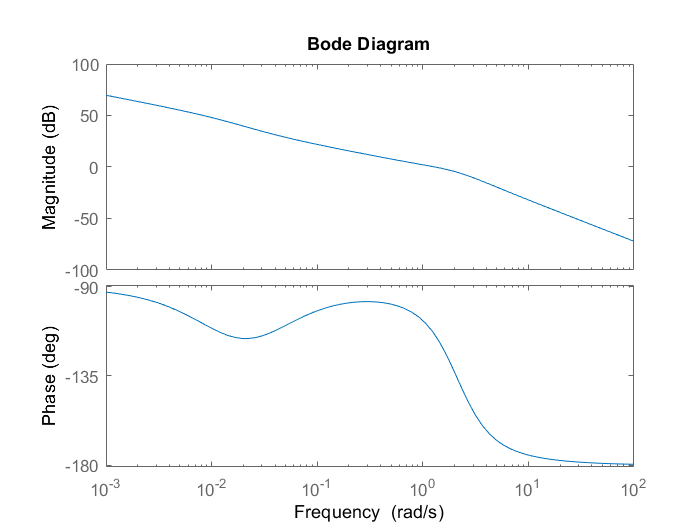


bode(L)

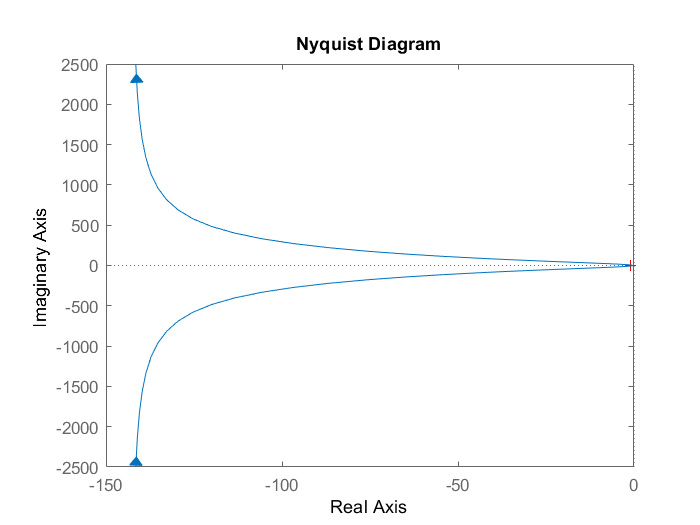

nyquist(L)

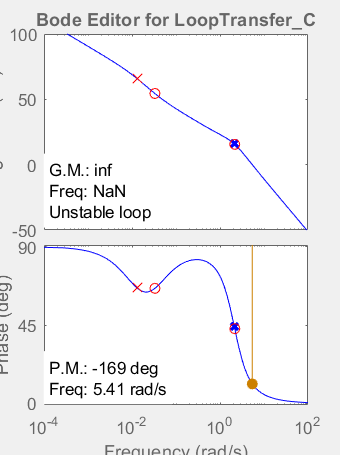

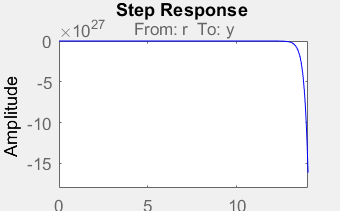

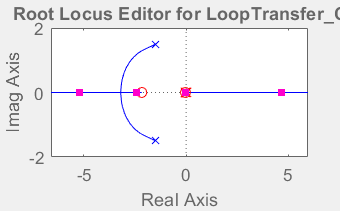


% NicholsEren(L, omega, Sp0, Tp0);

% controlSystemDesigner(Gp,Gc,1,1)